filename = "Project\3 Minute Beethoven, Symphony No. 5.  🎼🎶🎵.wav"; %song input (we need to change the song because it is too basic because I was going to do it for a different project.

%read audio file
[audio, fs] = audioread("3 Minute Beethoven, Symphony No. 5.  🎼🎶🎵.wav");


t = (0:length(audio)-1)/fs ;%seconds of audio file

%plotting audio file
figure;

plot(t,audio) ;
title("Audio File");
xlabel("Time(seconds)");
ylabel("Amplitude");


%Power Spectrum of Audio
[p,f] = pspectrum(audio,fs);

%Convert Power to decibel(dB) using pow2db function
p_dB = pow2db(p);




%Adding Bass (Amplifying Low Frequencies) through lowpass filter
audio_bass = lowpass(audio,200,fs,'Steepness',0.85,'StopbandAttenuation',60);


%Power Spectrum of Bass Boosted Audio
[pb,fb] = pspectrum(audio_bass,fs);
%Convert Power to dB
pb_dB = pow2db(pb);

figure;
plot(f, p_dB, "Color", 'r', "DisplayName",'Original' );  
hold on
plot(fb, pb_dB,"Color", "b", "DisplayName", 'Bass Boosted')
legend show;
grid on;
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
title('Power Spectrum of Audio Signal - with Bass');
hold off

NewBassFile = 'audio_bass.wav';
audiowrite(NewBassFile, audio_bass, fs)


%Adding Treble (Amplifying High Frequencies) Yall can do this. I already
%gave yall the function.
audio_treble = highpass(audio,2000,fs,'Steepness',0.85,'StopbandAttenuation',60);
%Skibidi toilet will be mine yeah ohio town yeah diamonds to mine I'm on
%the big sigma grind yeah worried about imposters i am way to sus yeah ohio
%rizz yeah

%Power Spectrum of Treble Boosted Audio
[pt,ft] = pspectrum(audio_treble,fs);

%Cover Power to dB
pt_dB = pow2db(pt)

pt_dB =  -131.6576 -132.2090
 -131.4449 -131.9860
 -130.6465 -131.1581
 -129.0346 -129.5112
 -126.7490 -127.2076
 -124.2022 -124.6679
 -121.7127 -122.2081
 -119.4228 -119.9682
 -117.3719 -117.9863
 -115.5577 -116.2582



%Graph 
figure;
plot(f, p_dB, "Color", 'r', "DisplayName",'Original' );  
hold on
plot(ft, pt_dB,"Color", "g", "DisplayName", 'Treble Boosted')
legend show;
grid on;
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
title('Power Spectrum of Audio Signal - with Treble');
hold off
NewTrebleFile = 'audio_treble.wav';
audiowrite(NewTrebleFile, audio_treble, fs)

%Midrange frequencies (watesigma is even that)


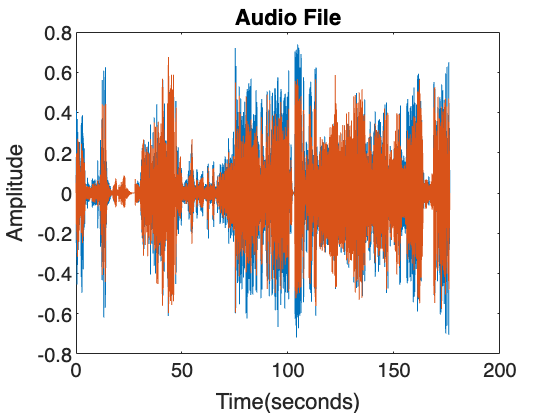

plot(f, p_dB, "Color", 'r', "DisplayName",'Original' );  
hold on
plot(fb, pb_dB,"Color", "b", "DisplayName", 'Bass Boosted')
plot(ft, pt_dB,"Color", "g", "DisplayName", 'Treble Boosted')
legend show;
grid on;
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
title('Power Spectrum of Audio Signal - with Bass');
hold off

%Play the music
audioplayer('audio_bass.wav', 1)

Error using audioplayer (line 139)
When creating an audioplayer object from an audio signal, all input arguments must be numeric.